# Modism Project 3 - 1A

Rowan Jansens and Anthony Costarelli

## Question

On November 24th, 2021, a spacecraft named DART was launched. Its mission is to fly itself into an asteroid to test out weather such an impact could be a feasible method to redirect an earth-threating object. 

In this model, we are **predicting** whether DART would have been able to redirect the Chicxulub impactor (the asteroid hypothesized to have led to the dinosaur extinction) and if so, how many years in advance would DART have needed to collide with the impactor to successfuly deflect it from Earth.

This is an interesting question because it can provide context into the scale of comic phenomena such as the Chicxulub impact in addition to what power humans have in influencing such an event. Additionally, it could highlight the areas of research that will be especially important if we are to redirect asteroid in the future.

## Method

### Visual Representation

We will begin by developing a 2d model of our system as depicted in the diagram below.

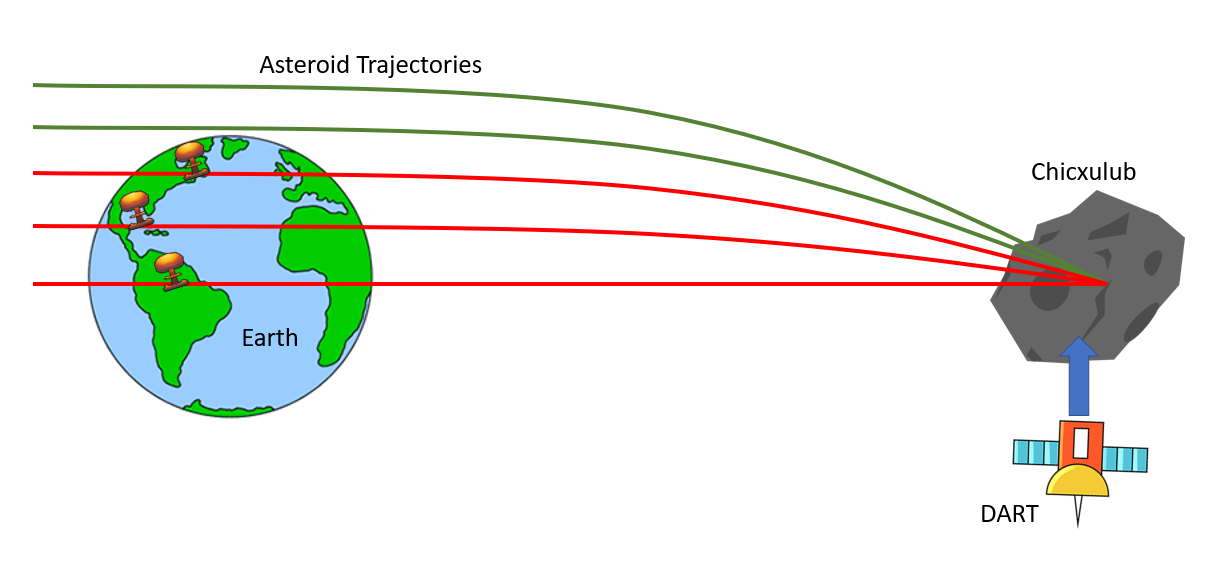 

### Mathematircal Representation

The earth is placed statically at the origin while the Chicxulub impactor is free to move around according to Newtonian physics in the equation for standard gravitation:

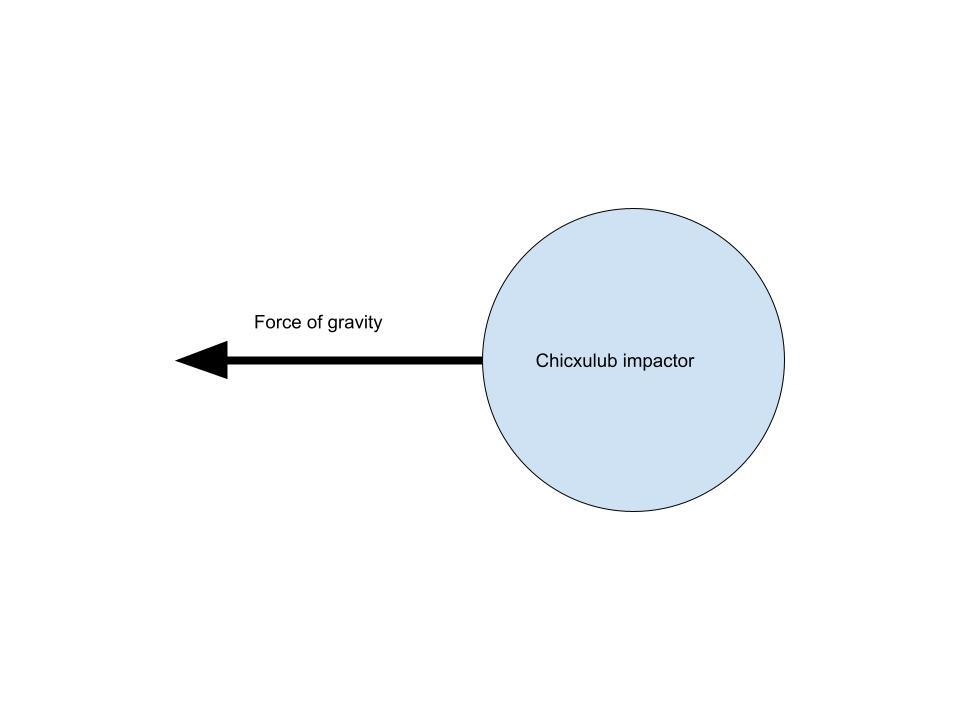

We will use the equation for standard gravitation to determine the motion of the asteroid.


$$\frac{d^2x}{dt^2} = -G\frac{m_{earth}}{x^2}\hat{r}$$


- Where $\hat{r}$ is a unit vector that points from the center of the asteroid to the origin (center of earth).

This equation can be decomposed into the following first order system:

- 
$$\frac{dv}{dt} = -G\frac{m_{earth}}{x^2} \hat{r}$$


- 
$$\frac{dx}{dt} = v$$


We will need position and velocity data for the Chicxulub asteroid however this data is not widely available. What we do have access to are the final conditions of the asteroid (position, speed, and impact angle) which means we can run our model “backwards” to simulate what the Chicxulub trajectory might have looked like. We do this by setting the initial conditions of the model to the “final conditions” of the asteroid, remembering to multiply the initial velocity by -1. Then we run the model “backwards” for as long as we need in order to generate the necessary position and velocity data.

- 
$$\frac{dv}{dt} = -G\frac{m_{earth}}{x^2} \hat{r}$$


- 
$$\frac{dx}{dt} = v$$


When the DART spacecraft collides with the asteroid, we will use conservation of momentum to find the new velocity of the asteroid at the time of collision. This momentum transfer is government by the following equations:

- 
$$P_{chic} + P_{DART} = P_{comb}$$


- 
$$m_{chic}v_{chic} + m_{DART}v_{DART} = m_{comb}v_{comb}$$


- 
$$v_{comb} = \frac{m_{chic}v_{chic} + m_{DART}v_{DART}}{m_{comb}}$$


### Computational Representation

In our initial model, we chose an arbitrary inital position and velocity for the Chicxulub impactor and then watched as it crashed directly into the Earth.  In this first iteration, we parameter-swept the distance from the Earth at which the DART collides with the impactor.

However, to make our model more reaslitc, we decided to simulate what the real Chixulub trajecotry might have looked like in our 2d system. We did this by setting the initial conditions of our model to the final conditions of the asteriod (speed, position, and inclanation: values which have been extesilve reaserch and modled by others). Then we ran the model "backward" by multipling the initlal velocity by -1.  This left us with a sumlated trajectry of what the Chicxulub crater might have looked like for as far back in time as we run the simulation. In this new interation of our model, we parameter-sweep the time before impact at which the DART collides with the impactor, where the position of the astriod at that time is determined using the simulated trajectory. Since the trajectory of the real asteroid is essentially the focus of our model, we believe that this was an important iteration in helping us to genereate meanigful results.

global year2sec
year2sec = 364.25 * 24 * 3600;

years = 0.01 * year2sec;
chic_data = chicxulub(years, 100);  %generate data for the asteriod for 0.01 years at 0.001 hour timesteps
plot_traj(chic_data); %plot the trajectory
axis([-6500 15000 -6500 20000])

This graph shows the first (or last) few datapoints from the reconstructed trajectory.

When the DART spacecraft collides with the asteroid, we will use conservation of momentum to find the new velocity of the asteroid at the time of collision. This momentum transfer is government by the following equations:

- 
$$P_{chic} + P_{DART} = P_{comb}$$


- 
$$m_{chic}v_{chic} + m_{DART}v_{DART} = m_{comb}v_{comb}$$


- 
$$v_{comb} = \frac{m_{chic}v_{chic} + m_{DART}v_{DART}}{m_{comb}}$$


Initial testing revealed that even if the DART impacted Chixulub was 1000 of years before earth impact, the alterd trajecotry would be insignificant. We used a crude calculation using the angle between the unperturbed trajecotry and the trajecotry after DART impact to hypothesize that the time required would be on the scale of hundreds of thousands of years. With this in mind, we made a decision to increase the DART mass significantly so that we woudl not need to model hundreds of thousands of years adn could instead see results in just a few years. While this change do make our mode results non-realisitc, it does not effect how the systenm behaves and allows for efficent visualive the system.

### Assuptions

There are obviosly a number of assumtions and simplicifcations that we are wmaking in this model. On of the first asumption we made is that the ateriod is only effected by earths gravity. In reality, the astriod will exprice the gravity of the sun as well as other planets. All of these objects would cahge the true trajectory of the astriod. However, we did not think that inlcuding the effects fo these bodies woudl signifactly change our results.

We are also making the assumption that the collision between DART and the asteriod is a 100% effiicent momentum transfer. As tjos collision is happening in deep space, this seems to be a fair assumption. 

We also made the assumption that the mass of the asteroid is constant. This may not be the most accurate because in reality, the asteroid will loose considerab mass as its enters earths atmosphere. However, sources providing the asteroid's actual mass give a considerably large range, so the cahnge in mass is likly withint the uncertanty of the mesurment.

Additoinaly, we are not modleing aerodaynami drag as the asteriod enerts the atmoshpere but this is likly insignifcat considering how thin the atmoshere is at the scale and speed of Chicxulub.

### Verification

To verify our model, we simulated the Chicxulub trajectory using the “backward” simulation. Then we ran the simulation “forward” in time (whiohuth DART impacting it) and found that the asteroid fell back to earth in a nearly identical trajectory in addition to landing in the same location that it “took off” from. This proved that the “backward” calculation is a plausible way to calculate an approximate trajectory. This test also demonstrated that the ODE45 event function that we are suing can correctly detect the asteroid colliding with the earth. 

We also looked at how the energy of the system changes before and after the DART collision. We found that the system loses energy, but this is the expected results consider that we did not add any constraints to this value in the model. If energy were modeled/constrained, the lost energy would have likely manifested itself in the sound and explosion associated with the impact.

### Validation

Although we struggled to get our model to work using realistic numbers for the mass and velocity of DART, we can still carry out validation to determine weather our model is on the right track. The DART spacecraft is estimated to change the velocity of its target asteroid (Dimorphos) by 0.4mm/s. We simulated that DART would change the velocity of Chixulub by around 5.8 e-7 mm/s. However, the mass of Chicxulub is much greater than the mass of the Dimorphos.  Taking this into account by multiplying each change in velocity by the mass of the body, we can compare the change in momentum.


$$\Delta P_{chic} = 4.0 * 10^9$$



$$\Delta P_{dim} = 1.9 * 10^9$$


These two numbers are within an order of magnitude of each other. 

Initial testing revealed that even if the DART impact was a thousands of years before earth impact, the trajectory would not be altered significantly. While this might be semi-realistic, there is some error involved with using both very large and very small numbers. The change in angle of the velocity after DART impact is so small that it cannot be correctly computed with ordinary double precision floating point number. For the sake of generating results, we opted to increase the mass of DART from 500kg to 1e11 kg just so that we might see a difference in a more measurable timeframe.

We make the assumption that the collision between DART and the asteriod is a 100% effiicent momentum transfer. This collision is happening in deep space, so we believe this is a fair assumption. We also made the assumption that the final mass of the asteroid is equivalent to its initial mass. This may not be the most accurate assumption because the asteroid likely burned up considerably as it entered Earth's atmosphere. However, sources on the asteroid's actual mass give a considerably large range, so it seems that, in general, no one is quite sure of the proper mass.

In our initial model, we chose an arbitrary trajectory for the Chicxulub impactor where it crashes directly into the Earth. However, we did some research and found the real impact angle and then created a function that calculates a more-realistic trajectory for the impactor. In the first iteration of our model, we parameter-swept the distance from the Earth at which the DART collides with the impactor. In this current interation of our model, we parameter-sweep the time at which the DART collides with the impactor, where the position is determined using the impactor's calculated trajectory. Since the trajectory of the asteroid is essentially the focus of our model, we believe that making the trajectory into a better representation of reality was an important iteration.

Verification

Running our model in forward and "reverse" using the same angle of impact produces the same trajectory, which suggests that our code for running the model in reverse works properly:

Validation

We used the final conditions of the asteroid (i.e. its momentum and impact angle), which were determined from through various archeological explorations of the impact crater, to run our model in reverse and determine a more accurate trajectory for the asteroid. While this is still not likely the real trajectory, it is the most accurate we can create in a two-body celestial system.

## Results

global year2sec
year2sec = 364.25 * 24 * 3600;


## Results

max_time = 4*year2sec;
dt = 100;
chic_data = chicxulub(max_time, dt); % calculate the trajectory of the impactor

This graph shows the first (or last depending on how you think about it) few datapoints from the reconstructed trajectory.

When the DART spacecraft collides with the asteroid, we will use conservation of momentum to find the new velocity of the asteroid at the time of collision. This momentum transfer is government by the following equations:

- 
$$P_{chic} + P_{DART} = P_{comb}$$


- 
$$m_{chic}v_{chic} + m_{DART}v_{DART} = m_{comb}v_{comb}$$


- 
$$v_{comb} = \frac{m_{chic}v_{chic} + m_{DART}v_{DART}}{m_{comb}}$$


Initial testing revealed that even if the DART impact was a thousand years before earth impact, the trajectory would not be altered significantly. While this might be semi-realistic, there is some error involved with using both very large and very small numbers. The change in angle of the velocity after DART impact is so small that it cannot be correctly computed with ordinary double precision floating point number. For the sake of generating results, we opted to increase the mass of DART from 500kg to 1e11 kg just so that we might see a difference in a more measurable timeframe.

We make the assumption that the collision between DART and the asteriod is a 100% effiicent momentum transfer. This collision is happening in deep space, so we believe this is a fair assumption. We also made the assumption that the final mass of the asteroid is equivalent to its initial mass. This may not be the most accurate assumption because the asteroid likely burned up considerably as it entered Earth's atmosphere. However, sources on the asteroid's actual mass give a considerably large range, so it seems that, in general, no one is quite sure of the proper mass.

In our initial model, we chose an arbitrary trajectory for the Chicxulub impactor where it crashes directly into the Earth. However, we did some research and found the real impact angle and then created a function that calculates a more-realistic trajectory for the impactor. In the first iteration of our model, we parameter-swept the distance from the Earth at which the DART collides with the impactor. In this current interation of our model, we parameter-sweep the time at which the DART collides with the impactor, where the position is determined using the impactor's calculated trajectory. Since the trajectory of the asteroid is essentially the focus of our model, we believe that making the trajectory into a better representation of reality was an important iteration.

Verification

Running our model in forward and "reverse" using the same angle of impact produces the same trajectory, which suggests that our code for running the model in reverse works properly:

Validation

We used the final conditions of the asteroid (i.e. its momentum and impact angle), which were determined from through various archeological explorations of the impact crater, to run our model in reverse and determine a more accurate trajectory for the asteroid. While this is still not likely the real trajectory, it is the most accurate we can create in a two-body celestial system.

## Results

max_time = 4*year2sec;
dt = 100;
chic_data = chicxulub(max_time, dt); % calculate the trajectory of the impactor


[t, d, i] = trajectory(year2sec * 0.5, dt, chic_data);
plot_traj([t d])

The following figure shows a sweep of different DART collision times. A green trajectory is one that demonstrates a successful collision (i.e.  DART ends up deflecting the asteroid from the Earth, represented by the green circle), and red trajectory demonstrates an unsuccessful collision.


dt = 100;
t_range = year2sec * 0.1 : year2sec * 0.2 : year2sec * 2;
impacts = zeros(2, length(t_range));
figure
    clf
    x = linspace(0,2*pi,100);
    y = linspace(0,2*pi,100);
    x = 6378*sin(x);
    y = 6378*cos(y);
    
    
    
    hold on
    patch(x, y, "green")
    

for i=1:length(t_range)
    [t, X, impact] = trajectory(t_range(i), dt, chic_data); % if DART hits at max_time-i, will the impactor impact?
    impacts(1,i) = ~isempty(impact);
    impacts(2,i) = min(vecnorm(X(:,1:2)'));
    if isempty(impact)
        plot(X(:, 1)/1000, X(:, 2)/1000, ".-", "Color", [0.4660 0.6740 0.1880], "LineWidth", 0.5, "MarkerSize", 5)
    else
        plot(X(:, 1)/1000, X(:, 2)/1000, ".-r", "LineWidth", 0.5, "MarkerSize", 5)
    end
end
    
    xlabel("km")
    ylabel("km")
    title("Trajectory")
    axis equal
    axis([-10000 60000 -10000 30000])
    hold off

The following diagram is another representation of the above sweep. The y-axis has values 1, meaning the asteroid does hit the Earth (not desirable), and 0, meaning the aseroid does not hit the Earth. This diagram shows after what point in time that all DART impacts would be successful.

figure
clf
yyaxis right
plot(t_range / (365*24), impacts(2,:))
ylabel("Minimum Distance (km)")

yyaxis left
plot(t_range / (365*24), impacts, ".-", "Markersize", 20)
xlabel("Time of DART impact (years before potential earth impact)")
ylabel("Earth Impact")
ylim([-0.5 1.5])
yticks([0 1])

This shows that the 100 Teragram DART would have had to collide with the impactor at least 3 years in advance in order to deflect it enough as to not hit the earth.

We also performed a "therotical-upper-bound" simuulaiton where DART has the mass of the International Space Station (the heaviest man-made spacecraft) and the velocity of Voyager I (the fastest man-made spacecraft). We used our rought calucaiton stategie to estime the timefrae required and then ran this value through our model. 

We found that it would take 80000 years for a DART of this size and speed to be able to redirect the Chicxulub impactor.

## Interpretation

Theses initial results show that if we were able to launch a rocket that weighs 0.2 million times as much as the real DART spacecraft, we would only need to impact the Chicxulub asteroid three years in advance in order to redirect it safely away from earth.

Our first results show that a model of the DART would be able to deflect the impactor 130,000 years in advance, and our second results show that a model of  an "ideal" DART with the mass of the International Space Station (the heaviest man-made spacecraft) and the velocity of Voyager I (the fastest man-made spacecraft) would be able to deflect the impactor 80,000 years in advance. This latter number can be considered our lower bound if we consider a range of space crafts with different momentums, and even though it is an unrealistic spacecraft, it still cannot deflect the impactor in any realistic amount of time. Additionally, these numbers does not consider the travel time required for DART to meet the asteroid. Ultimately, it is not realistic for the DART to have been able to deflect the Chicxulub impactor and save the dinosaurs.

Our model is limited in that we don't calculate the travel time for the DART to reach the asteroid before impacting; we only start keeping track of time upon the DART's impact. This means that our numbers don't give us the best reading of feasability because we believe that part of this idea's being feasible is considering the total time for the idea to be put into effect. However, even without considering the DART's travel tiem, we can see that the impact would need to happen so unrealistically far in advance that if we were to add the DART's travel time, that number would only seem more fantastically unrealistic. In other words, given our order of magnitude, it would not change our answer.

In the next iteration of our model, we are considering adding a third body (the sun) as well as making some optimizations so that we can run our model with a realistic DART mass.

In our next iteration, we would consider adding a third body -- the sun. This would help to give our asteroid a more realistic path

## Sources

- Chicxulub momentum data: [https://www.nature.com/articles/s41467-020-15269-x](https://www.nature.com/articles/s41467-020-15269-x) 

- DART momentum data: [https://www.nasa.gov/planetarydefense/dart/](https://www.nasa.gov/planetarydefense/dart/) 

- Conservation of momentum: [https://www.grc.nasa.gov/www/k-12/airplane/conmo.html](https://www.grc.nasa.gov/www/k-12/airplane/conmo.html) 